# INPUT MuRAT3D - Campi Flegrei

This is an input file for the program Multi-Resolution Attenuation Tomography (MuRAT). It refers to the following area:

## GENERAL FIELDS AND FIGURES

INPUTS in this section set the directory space and the type of simulation. All inputs are saved in the $.input$ field of the Murat structure variable.

### Directories and file architecture

Best practice is to create a new folder where you create your workspace. The code will save all your results inside a new folder he creates in the directory. In the example there are several directories containing the sac files (sac_*). The results of this example will be created in subfolders inside the MSH folder.

**The working directory is the folder where you downloaded MuRAT.**

#### Data directory

The data directory contains *.sac* files (beware of the difference between *.sac* and *.SAC*). For this example we will use data in the sac_MSH folder. Inside this folder, only vertical (Z) seismograms are stored:

Murat.input.dataDirectory           =   'sac_Flegrei';

If you want to use two or three-component recordings, you have to store them  into a single folder, but the three components must be in the exact order **E,N,Z**. For an example see the Toba application.

#### Label

Afterwards you specify the name of the folder that will store results and figures - it will appear in your working directory:

Murat.input.label                   =   'CF1984';

#### Sequential or parallelized loops

In MuRAT3D you can choose between a sequential (***0 ****- Murat_data*) or parallelized (***1**** - Murat_dataParallelized*) forward loop. In the parallelized case, select the number of workers. In this example, we are working with the parallelized code . 

Murat.input.parallelized            =   1;
Murat.input.workers                 =   8;

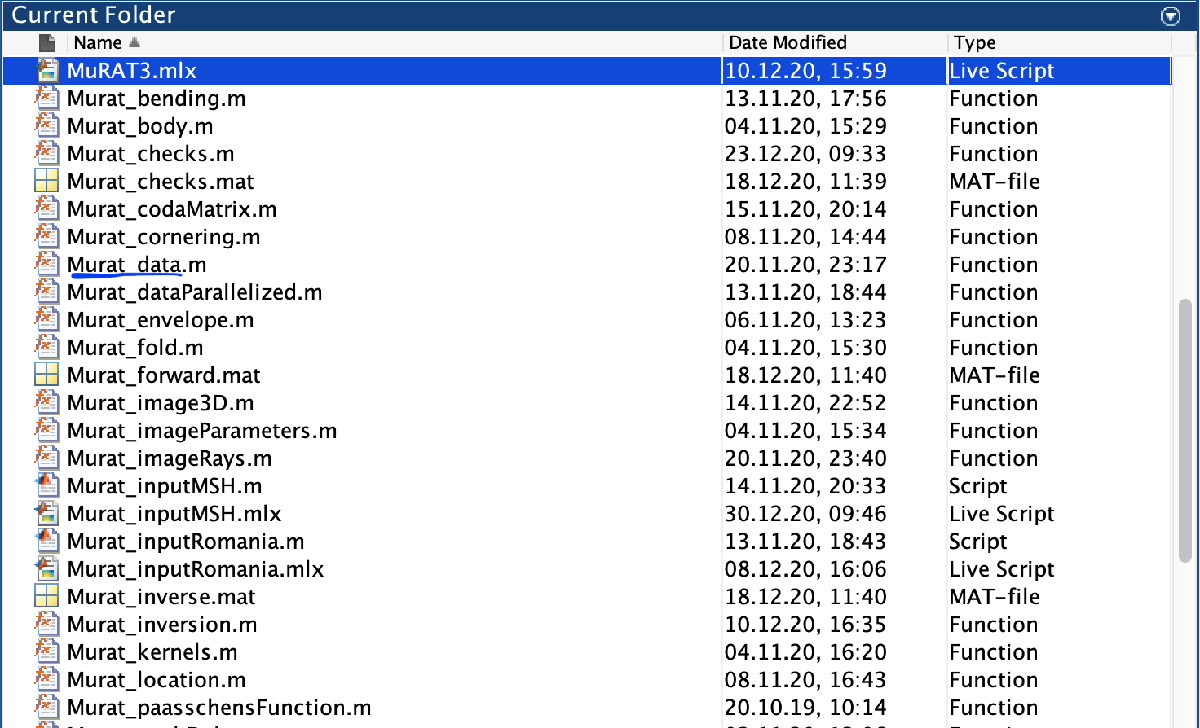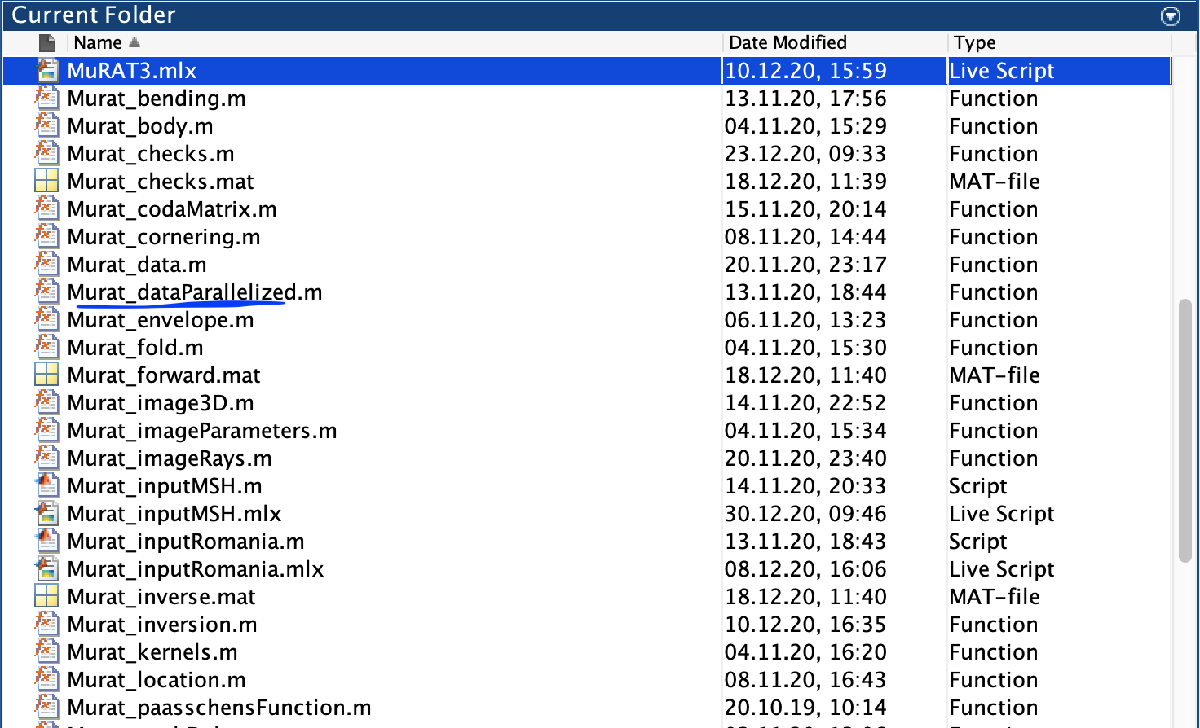

## DATA DRIVEN CHOICES - WAVEFORMS

The in this section set all the variables required by data processing. This includes data choises, as setting the name of the variables in SAC and all the attributes that are needed for the three kinds of imaging.

As MuRAT3D is designed to work with *sac* files only, it is necessary to set the path to their peaking and zero time. This means that the files have to be peaked beforehand, and the origin time from the localization must be included in the haeder. The routines for loading the files have been mostly created by [Zhigang Peng ](http://geophysics.eas.gatech.edu/people/zpeng/)and co-workers and downloaded from their [Introduction to SAC](http://geophysics.eas.gatech.edu/people/zpeng/Teaching/Sac_Tutorial_2006/) webpage.

#### Origin, P- and S-wave times

So first set origin time, P-wave peaking and S-wave picking. If you don't have the origin time and S-wave times at hand you can mark it as unknown (***[]*****)**. The P-wave picking is mandatory. 

Murat.input.originTime              =   'o';
Murat.input.PTime                   =   'a';
Murat.input.STime                   =	't0';

Afterwards, you need to choose the phase you are interested in - P- (2) or S- (3). In our case it is obviously P- as we have no S-wave picking.

Murat.input.POrS                    =	3;

#### Central Frequency

You need to set the central frequency (Hz) according to your spectrograms. General practice is to vary it across your spectra (see [De Siena et al. 2016, EPSL](https://www.sciencedirect.com/science/article/abs/pii/S0012821X16300437)) for absorption and scattering mapping or focus on a given frequency ([De Siena et al. 2014, JGR](https://agupubs.onlinelibrary.wiley.com/doi/abs/10.1002/2014JB011372)) for direct-wave attenuation imaging.

Murat.input.centralFrequency        =	[3 12 18];

#### Number of components

You can work with 1 vertical or horizontal (*1*), 2 horizontal (*2*) or three components(*3*). If using more than one component, the order MUST BE: WE, SN, Vertical or SN, WE, Vertical. In this example we work with the vertical component only.

Murat.input.components              =	3;

## PEAK DELAY

Scattering (peak delay) measurements relies on measurements of coherent waves.

Peak delay is a standard measurements of forward scattering in regional scale-mapping since [Takahashi et al. 2007, GJI](https://academic.oup.com/gji/article/168/1/90/581022?login=true). The tomographic developments of this work (same lead author, years 2008 and 2009) are important and we plan to include them for scattering imaging in the future. To do so, we will need to consider the order of the modified Bessel function of second kind, describing the von-Kármán type random medium with a new input as:

Here, we approach the problem by simply adding a ray-tracing strategy to the system, assuming that the sensitivity follows the seismic ray  Also we bring it to 3D and apply it to P-waves with the  approach described in [De Siena et al. 2016, EPSL](https://www.sciencedirect.com/science/article/abs/pii/S0012821X16300437).

#### Minimum and maximum peak delays

To do so we need to set a minimum peak delay (*s*) considering scattering in the area and frequency. If using P wave this is important, as they can be sometimes more energetic than S-waves, biasing our measurements, but this is not the case at Mount St. Helens. Obviusly we also need to set the maximum peack-delay (*s*) to avoid peaking anomalous surface waves - see  [Takahashi et al. 2007, GJI](https://academic.oup.com/gji/article/168/1/90/581022?login=true).

Murat.input.minimumPeakDelay        =	0.5;
Murat.input.maximumPeakDelay        =	5;

## DIRECT WAVE ATTENUATION

Total attenuation (inverse Q) measurements also relies on measurements of coherent waves.

Total attenuation with the coda-normalization method is today astandard in volcano tomography. First used by [Del Pezzo et al. 2006, PEPI](https://www.sciencedirect.com/science/article/pii/S0031920106001282) at Mount Vesuvius, it has been the core of MuRAT1.0, the seminal code published in [De Siena et al. 2014, JVGR](https://www.sciencedirect.com/science/article/abs/pii/S0377027314000961). The method has been applied so far to Campi Flegrei ([De Siena et al. 2010, JGR](https://agupubs.onlinelibrary.wiley.com/doi/full/10.1029/2009JB006938); De Siena et al. 2017, Scientific Reports), Mount St Helens ([De Siena et al. 2014, JGR](https://agupubs.onlinelibrary.wiley.com/doi/full/10.1002/2014JB011372)), Deception Island ([Prudencio et al. 2015](https://link.springer.com/article/10.1007/s10712-015-9322-6)); Tenerife ([Prudencio et al. 2015](https://link.springer.com/article/10.1007/s10712-015-9333-3)) and Long Valley ([Prudencio & Manga, 2020](https://academic.oup.com/gji/article-abstract/220/3/1677/5650518)). There are three more volcanoes where the application is undergoing.

#### Spectral decay

The method relies on the measurements of both direct and coda wave energy. Therefore we need to set the spectral energy decay of the coda wavefield. The spectral decay has to be set for prdominance of 2D surface  (0.5), diffusive (1.5) or body waves (2). At MSH it is the first case.

Murat.input.spectralDecay           =	2;

#### Window lengths for body waves and coda

Then we set the length of the window used to measure noise and direct wave intensity, trying to smooth radiation pattern effects. Discussions on the topic can be found in [De Siena et al. 2009, PEPI](https://www.sciencedirect.com/science/article/pii/S0031920108003178?casa_token=FBQxspuFhPcAAAAA:P1a7DnDvjJpf9HVV1JzKsX-fzONnmmuUYMOZhAKOdRd_5Al7EHb5AydQAhjAwiIyBhMOq1xKNA) and [De Siena et al. 2010, JGR](https://agupubs.onlinelibrary.wiley.com/doi/abs/10.1029/2009JB006938), but the choise is as usual dependent on data.

Murat.input.bodyWindow              =	1;

#### Noise time

We also need the start of the window used to measure noise from the start of the recording. Set this in seconds.

Murat.input.startNoise              =	0.1;

#### Coda-to-noise ratio

The coda-to-noise energy ratio is used as a weight for the  inversion. Here you set the minimum accepted energy ratio.

Murat.input.tresholdNoise           =	2;

## CODA ATTENUATION

Coda attenuation (inverse Qc) is measured from the decay of the coda with laps time from the origin time of the earthquake.

Qc is a well know parameter for assesing tectonic structures ([Sato et al. 2012, Springer](https://link.springer.com/book/10.1007/978-3-642-23029-5)). In recent years it has been used as an imaging attribute at the regional ([Calvet et al. 2013, Tectonophysics](https://www.sciencedirect.com/science/article/abs/pii/S0040195113005490); [Borleanu et al. 2017, Tectonophysics](https://www.sciencedirect.com/science/article/pii/S0040195117301476)), fault ([Napolitano et al. 2020](https://www.sciencedirect.com/science/article/pii/S1674987119301999); [Sketsiou et al. 2020, PEPI](https://www.sciencedirect.com/science/article/pii/S0031920119302122)) and, especially, volcanic scales ([Prudencio et al. 2013a, GJI](https://academic.oup.com/gji/article/195/3/1957/2874185?login=true); [Prudencio et al. 2013b GJI](https://academic.oup.com/gji/article/195/3/1942/626933);  [De Siena et al. 2016, EPSL](https://www.sciencedirect.com/science/article/abs/pii/S0012821X16300437); [De Siena et al. 2017, GRL](https://agupubs.onlinelibrary.wiley.com/doi/abs/10.1002/2017GL072507); [Gabrielli et al. 2020, GJI](https://academic.oup.com/gji/article-abstract/222/1/169/5814316)).

### Lapse times and sensitivity kernels

In MuRAT3D, we use the full 3D computational kernels devised by [Del Pezzo et al. 2018, Geosciences](https://www.mdpi.com/2076-3263/8/5/175) in the inversion approach proposed first by [De Siena et al. 2017, GRL](https://agupubs.onlinelibrary.wiley.com/doi/abs/10.1002/2017GL072507).

#### Starting lapse time and coda window length

Here you choose the start of the window used to measure coda wave energy and model kernels. The starting time of the coda window can be set directly in seconds ('**Constant**'), from the envelope peak ('**Peak**'), or depending on the P- or S-wave travel time, for example twice the S-wave travel time ('**Travel**'). If the chosen method is **Constant**, set start and length of the window.

Murat.input.lapseTimeMethod         =   'Constant';

If the chosen method is **Constant**, set the start of the window in seconds after the origin time. It it is **Peak**, set it to **[]**. If it is **Travel **select *Murat.input.startLapseTime* as the moltiplicative factor of the pahase you are using (e.g., **2** or **3**). Avoid this method if you do not know the S-wave time.

Murat.input.startLapseTime          =   7;

Finally set the length of the coda window in seconds.

Murat.input.codaWindow              =   5;

and coda window length. The true lapse time at which we calculate the kernels is half of the window. The window is also used (after normalizing for its length) in the coda normalization method.

#### MLTWA

Albedo amd extinction length

Murat.input.albedo                  =   0.5;
Murat.input.extinctionLength        =   0.02;

#### Refinement factor to speed up computation

As these kernels are computational intensive and require a full matrix of nodes to avoid singularities, we also use a computational treshold to reduce the computational time:

Murat.input.kernelTreshold          =	1;

This number divides the input grid so the higher it is the denser is the node spacing. A figure will also output the kernel in this grid.

### Measurement of Qc

MuRAT3D  implements either a linearised approach or a grid search approach to measure Qc. The linearised approach is the standard proposed first by Aki (e.g., [Havskov et al. 2016, BSSA](https://www.researchgate.net/publication/303510878_Coda_Q_in_Different_Tectonic_Areas_Influence_of_Processing_Parameters)) to best fit Qc after taking the logarithm of the energy. The uncertainties are derived from the simple minimum R-squared. The non linear approach models energy data measured on one-second windows across the envelope and minimizes the difference between data and model with a 1D grid search algorithm ([Napolitano et al. 2020](https://www.sciencedirect.com/science/article/pii/S1674987119301999)).  fUncertainties are given by the experimental probability density function of the misfit. In both cases, uncertainties play as a weight in the final inversion. The user needsto choos between the two options **'Linearized'** and **'NonLinear'**:

Murat.input.QcMeasurement           =   'Linearized';

#### Refinement factor to speed up computation

While the non-linear case just search for the minimum misfit, the linearized case needs a minimum accepted fit to the linearized equation. It is advisable to set a minimum treshold near to zero, so that only positive defined fit are accepted. The maximum possible R-square is one (perfect fit) so the choise is again dependent on the quality of the data. Here we use:

Murat.input.fitTresholdLinear       =	0.1;

iI is advisable to use a higher number in real applications, especially for arrays that cover the area satisfactorly.

## GEOMETRY AND VELOCITY

This section sets the details of the inversion grid. In MuRAT3D the coordinates of the model are in lat/lon, then they get converted in km. The vertical is in altitude above sea level. The velocity model can be 1D or 3D - if 3D all poins must be given in lat/long formats.

#### Origin and end points

Murat.input.origin                  =   [40.7745 14.06  500];
Murat.input.end                     =   [40.8700 14.20 -5500];

Then you need to set the number of nodes in the three directions. This is obviously dependent on the scale of your area. You will be playing alot with this to test your resolution.

#### Number of nodes

Murat.input.gridLat                 =   20;
Murat.input.gridLong                =   22;
Murat.input.gridZ                   =   12;

### Velocity model

With this version of the code you are always using an underlying velocity model. 

For the 1D case MuRAT provides you with *iasp91.txt*, the standard [IASPEI velocity model](https://academic.oup.com/gji/article/105/2/429/705789) and expands it to a false 3D. However, a standard crustal model is generally available everywhere on the Earth, so use that - but change it to the same format as the file provided, first column is depth, second is distance from the centre of the Earth, then third and fourth are P- and S-wave velocity.

#### Availability of velocity model

You can either use an available 1D (*0*) or a 3D (*1*) velocity model. At Campi Flegrei we use the 3D local earthquake tomography model of Battaglia et al. 2008, stored in *modvS_Flegrei.txt* in the folder **velocity_model**, so we set:

Murat.input.availableVelocity       =	1;
Murat.input.namev                   =   'modvSF_reducedMore.txt';

#### Average velocities

Even if we set the velocity model we still need the average crustal velocities if you have no info of origin time. It is highly recommended you have it in the haeder!

Murat.input.averageVelocityP        =   4;
Murat.input.averageVelocityS        =   2.3;

## RESULTS

### Inversion

We rely on the [regtools Matlab suite](https://de.mathworks.com/matlabcentral/fileexchange/52-regtools) from Per Christian Hansen. A great reference for the best sort of testing is [Rawlinson & Spakman, 2016](https://academic.oup.com/gji/article/205/2/1221/692880?login=true).

The code implements either a standard Tikhonov inversion based on singular value decomposition (**'Tikhonov'**) and an iterative conjugate graduate least square inversion minimizing both model norm and Laplacian (**'Iterative'**). The first inversion is obtained using the standard [regularization tools](https://de.mathworks.com/matlabcentral/fileexchange/52-regtools) from [Per Christian Hansen](https://de.mathworks.com/matlabcentral/profile/authors/869107). The second uses the [IR TOOLS for iterative regularization](https://link.springer.com/article/10.1007/s11075-018-0570-7). Copies of both packages are provided with the code.

Murat.input.inversionMethod         =   'Iterative';

#### Show L-curve

As you need to select the damping you can choose to output the L curves between residual and norm length ([Aster et al. 2013](https://www.sciencedirect.com/book/9780123850485/parameter-estimation-and-inverse-problems) - case **'Tikhonov'**) or the cost functions (case **'Iterative**'). Set either ***1*** or ***0***. In the latter case, set the damping for both Qc and Q inversions.

Murat.input.lCurve                  =   0;

However, you will likely test many different damping parameters and want to avoid seeing the same figure again, so you can just declare the damping for Qc and Q after looking at the figures. Remember doing it for each frequency:

Murat.input.lCurveQc                =   [0.4 0.4 0.4];
Murat.input.lCurveQ                 =   [0.04 0.04 0.04];

### Testing

#### Size and values of checkerboards

Also, if you want to test you results you need to create a checkerboard. The size of the checks can be  twice (*2*) or four times (*4*) node spacing.

Murat.input.sizeCheck               =   2;

each cell having alternating values of attenuation:

Murat.input.highCheck               =   0.02;
Murat.input.lowCheck                =   0.001;

#### Size and values of spikes

In MuRAT3D you set the origin ad end locations of the spike as:

Murat.input.spikeLocationOrigin     =   [40.8 14.08  0];
Murat.input.spikeLocationEnd        =   [40.84 14.12 -2000];

while its value is:

Murat.input.spikeValue              =   0.02;

### Plotting

The last inputs are:

- your preferred figure format - 'jpeg' (fast) or 'tiff' (for publication):

Murat.input.format                  =   'jpeg';

- the sections where you will slice your plots. MuRAT3D now saves everything in Paraview format (.VTK) but some checks in Matlab can be useful. You will see all of your figures on three sections cutting the models WE (degrees), SN (degrees), and horizontally (meters or km) at:

Murat.input.sections                =	[40.85 14.11 -2000];